# 180497C - EN2040 - Simulation Assignment

## 12/09/2021

**Question 01**

Generating a binary sequence D. (D ==> {0,1}, Pr(D=0) = Pr(D=1) = 0.5)

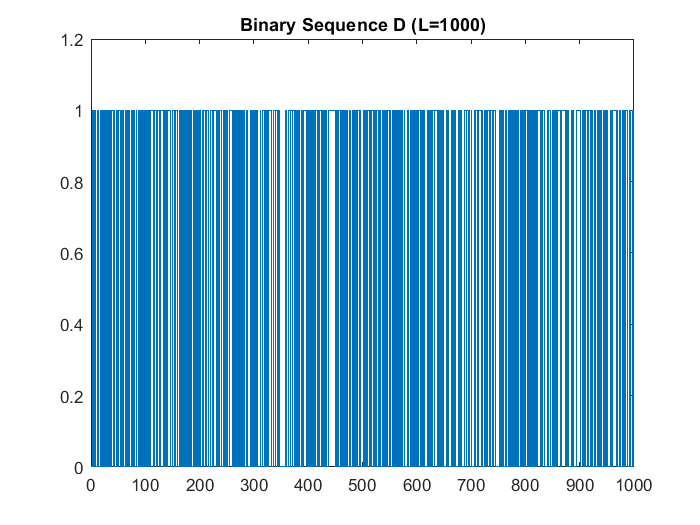

L = 1000; %Length of the sequence
D = zeros(1,L);

rng('default') %random generator is fixed
i = randperm(L,L/2); %random indices
D(i) = 1; % D--> equiprobable data array
stairs(D)
title('Binary Sequence D (L=1000)')
ylim([0,1.2])

Using the binary sequence to generate a stream of rectangular pulses. (A = 1)

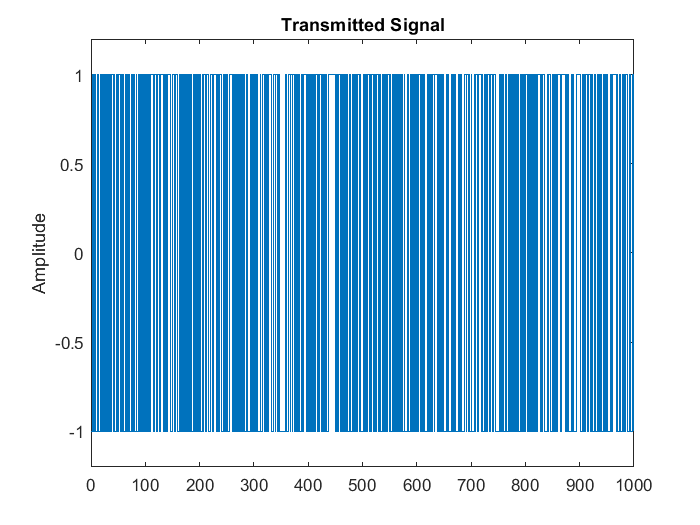

A = 1; %Amplitude of the rectangular pulses
S = zeros(1,L); %Stream of rectangular pulses
S(D==1) = A;
S(D==0) = -A;

stairs(S)
title('Transmitted Signal')
ylabel('Amplitude')
ylim([-1.2,1.2])

**Question 02**

Generating an AWGN sequence ($$\mu = 0, \sigma^{2} = 1$$)

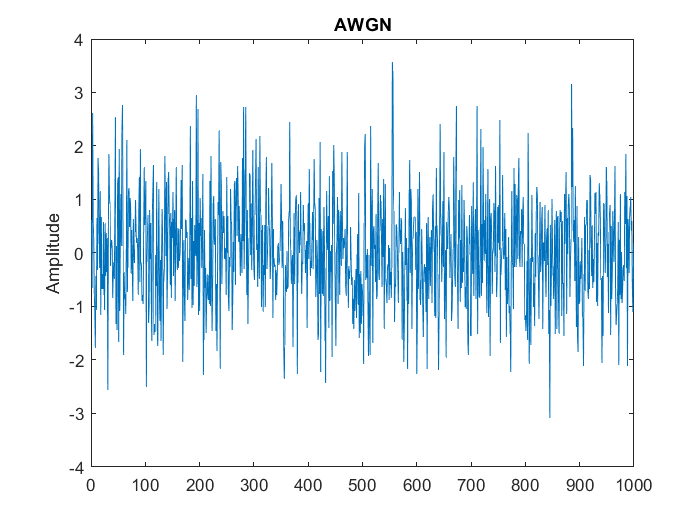

mu = 0; %Mean
sigma = 1; %Standard deviation
N = normrnd(mu, sigma, [1,L]); %AWGN

plot(N)
title('AWGN')
ylabel('Amplitude') 

**Question 03**

Received Signal (R = S + N)

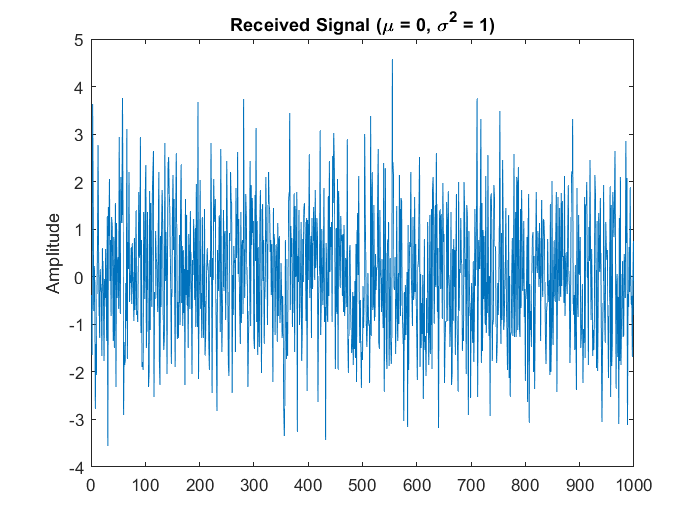

R = S + N; %Received signal

plot(R)
title('Received Signal (\mu = 0, \sigma^{2} = 1)')
ylabel('Amplitude')

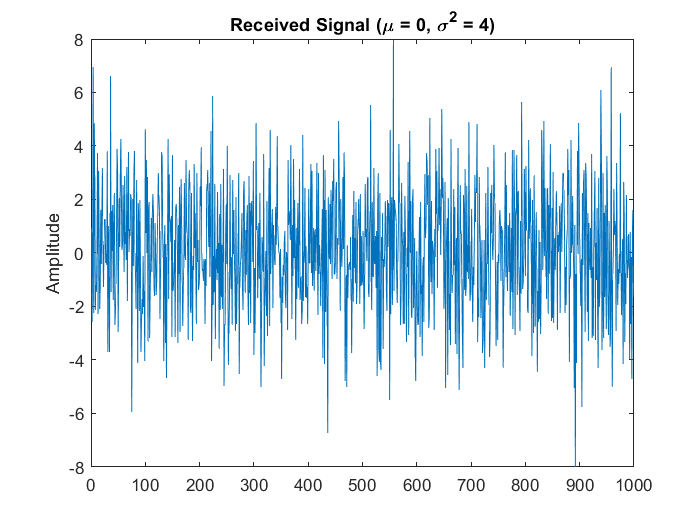


%Now let's plot the received signal when sigma = 2 and sigma = 3
R_sigma_2 = S + normrnd(mu, 2, [1,L]); %sigma = 2
plot(R_sigma_2)
title('Received Signal (\mu = 0, \sigma^{2} = 4)')
ylabel('Amplitude')

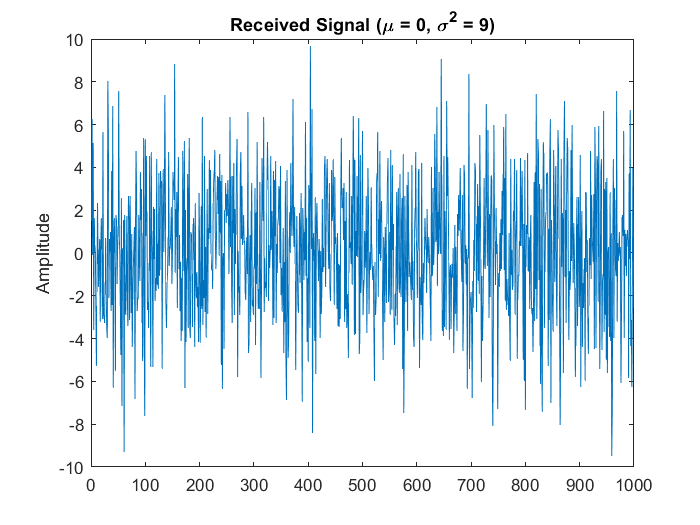


R_sigma_3 = S + normrnd(mu, 3, [1,L]); %sigma = 3
plot(R_sigma_3)
title('Received Signal (\mu = 0, \sigma^{2} = 9)')
ylabel('Amplitude')

**Question 04**

Decoding the received signal (Threshold $\tau = 0$)

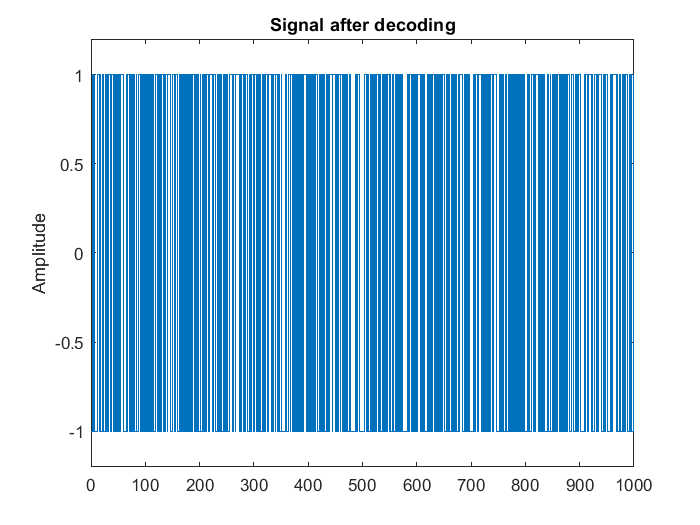

tau = 0; %threshold
Y = zeros(1,L); %Final output
Y(R>tau) = A;
Y(R<=tau) = -A;

stairs(Y)
title('Signal after decoding')
ylabel('Amplitude')
ylim([-1.2,1.2])

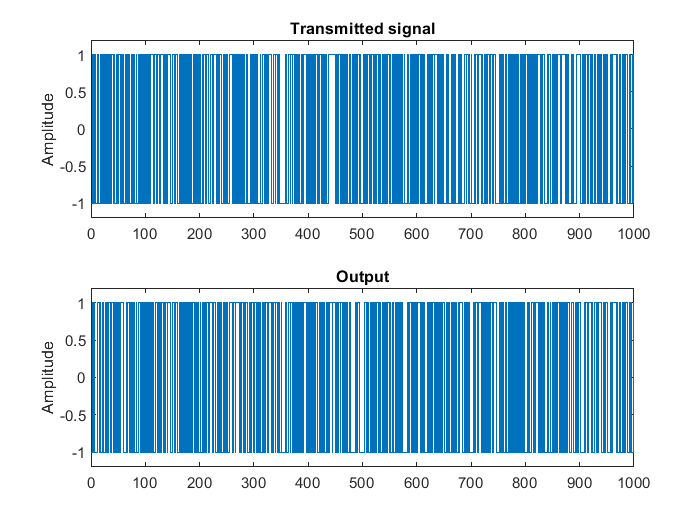


%Comparing the transmitted signal S and the output Y
figure;
subplot(2,1,1);
stairs(S)
title('Transmitted signal')
ylim([-1.2,1.2])
ylabel('Amplitude')

subplot(2,1,2);
stairs(Y)
title('Output')
ylim([-1.2,1.2])
ylabel('Amplitude')


%Calculating the error percentage
error = (sum(Y ~= S))*100/L'

error = 16.3000

sprintf('The error percentage is %.2f%%', error)

ans = 'The error percentage is 16.30%'

**Question 05**

L = 100000 (Repeating the steps 1-4)

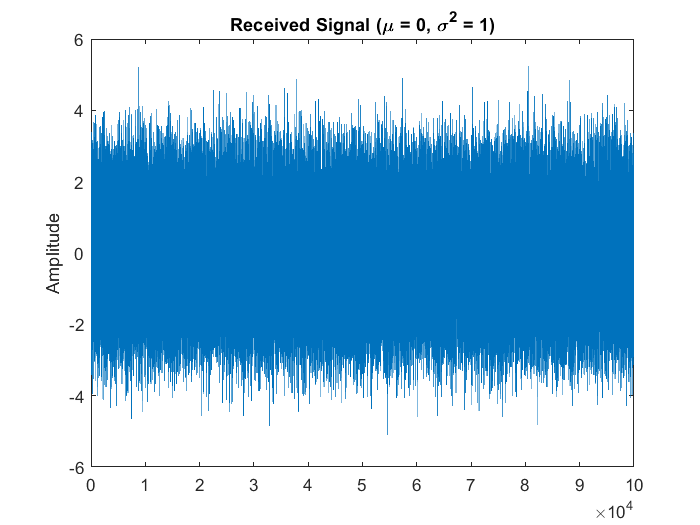

L = 100000; %Length of the sequence
D = zeros(1,L);

rng('default')
j = randperm(L,L/2); %random indices
D(j) = 1; % D--> equiprobable data array

A = 1; %Amplitude of the rectangular pulses
S = zeros(1,L); %Stream of rectangular pulses
S(D==1) = A;
S(D==0) = -A;

mu = 0; %Mean
sigma = 1; %Standard deviation
N = normrnd(mu, sigma, [1,L]); %AWGN

R = S + N; %Received signal
figure;
plot(R)
title('Received Signal (\mu = 0, \sigma^{2} = 1)')
ylabel('Amplitude')

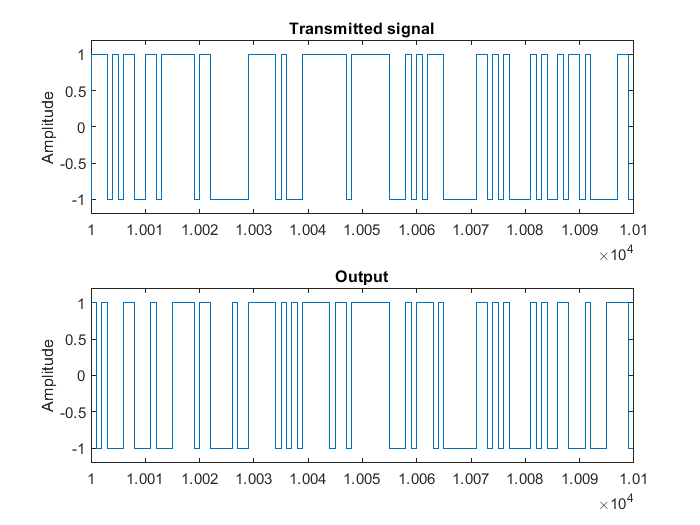


tau = 0; %threshold
Y = zeros(1,L); %Final output
Y(R>tau) = A;
Y(R<=tau) = -A;

%Comparing the transmitted signal S and the output Y
figure;
subplot(2,1,1);
stairs(S)
title('Transmitted signal')
ylim([-1.2,1.2])
xlim([10000,10100]) %limiting the x-range to view the differences
ylabel('Amplitude')

subplot(2,1,2);
stairs(Y)
title('Output')
ylim([-1.2,1.2])
xlim([10000,10100])
ylabel('Amplitude')


%Calculating the error percentage
error = (sum(Y ~= S))*100/L'

error = 16.2060

sprintf('The error percentage is %.2f%%', error)

ans = 'The error percentage is 16.21%'

Generating Histograms

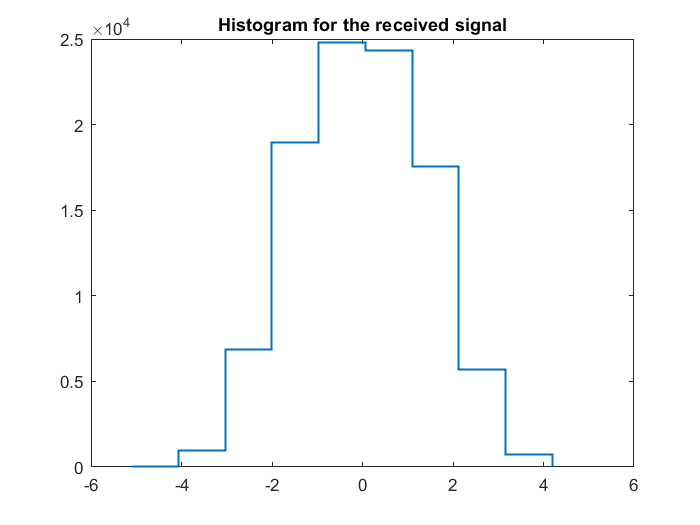

bins = 10; %no.of bins
range_R =  range(R);
max_R = max(R);
min_R = min(R);
class_width = range_R/bins;
bin_lims = min_R:class_width:max_R;

%initiating an array for the heights of the bars
heights = zeros(1,bins);

for i = 1:bins
    if i == bins
        heights(i) = sum(R>=bin_lims(i) & R<=bin_lims(i+1));
    else
        heights(i) = sum(R>=bin_lims(i) & R<bin_lims(i+1));
    end
end

%Creating the histogram
figure;
stairs(bin_lims(1:bins),heights,'LineWidth',1.2)
title('Histogram for the received signal')

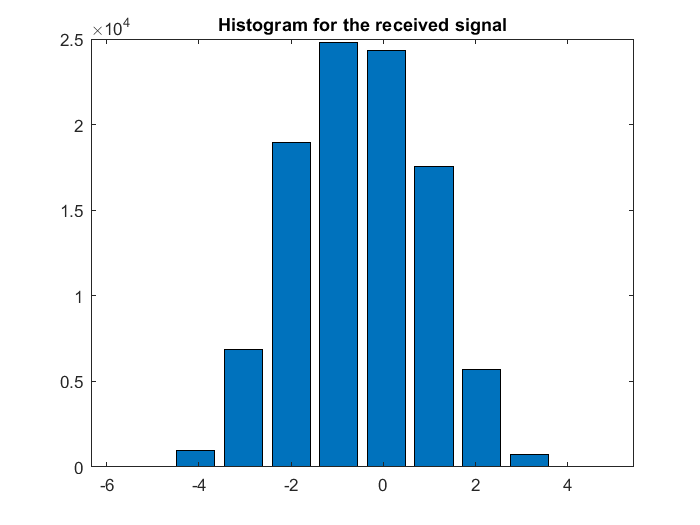


figure;
bar(bin_lims(1:bins),heights)
title('Histogram for the received signal')

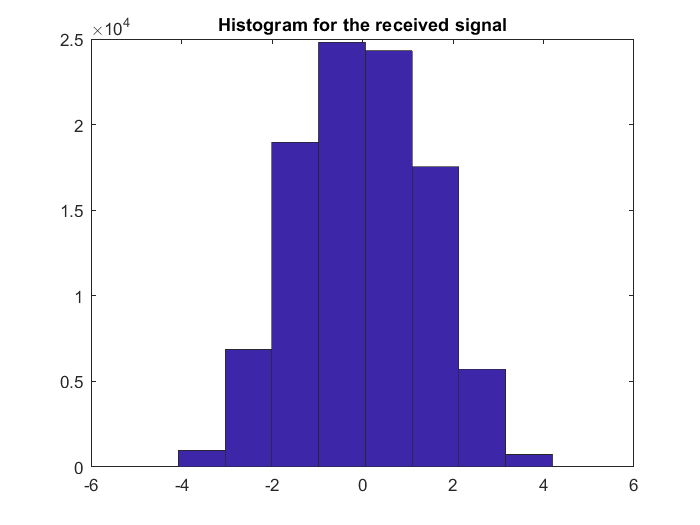


%Using the built-in function; hist
figure;
hist(R, bins);
title('Histogram for the received signal')

**Question 05 (a)**

Changing the no. of bins to 100

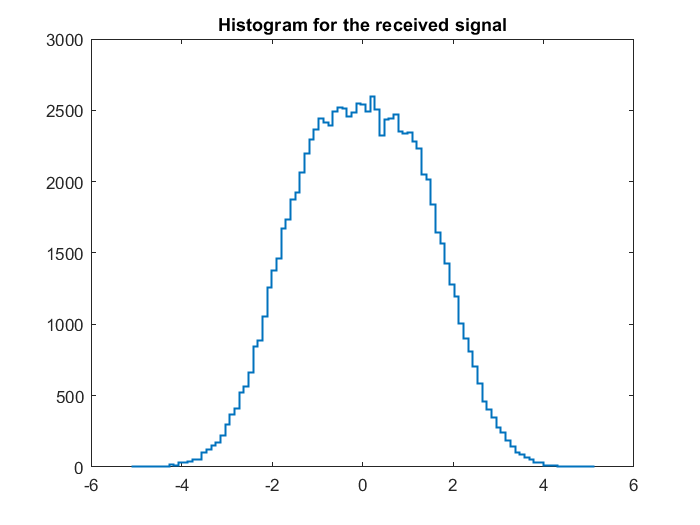

bins = 100; %no.of bins
range_R =  range(R);
max_R = max(R);
min_R = min(R);
class_width = range_R/bins;
bin_lims = min_R:class_width:max_R;

%initiating an array for the heights of the bars
heights = zeros(1,bins);

for i = 1:bins
    if i == bins
        heights(i) = sum(R>=bin_lims(i) & R<=bin_lims(i+1));
    else
        heights(i) = sum(R>=bin_lims(i) & R<bin_lims(i+1));
    end
end

%Creating the histogram
figure;
stairs(bin_lims(1:bins),heights,'LineWidth',1.2)
title('Histogram for the received signal')

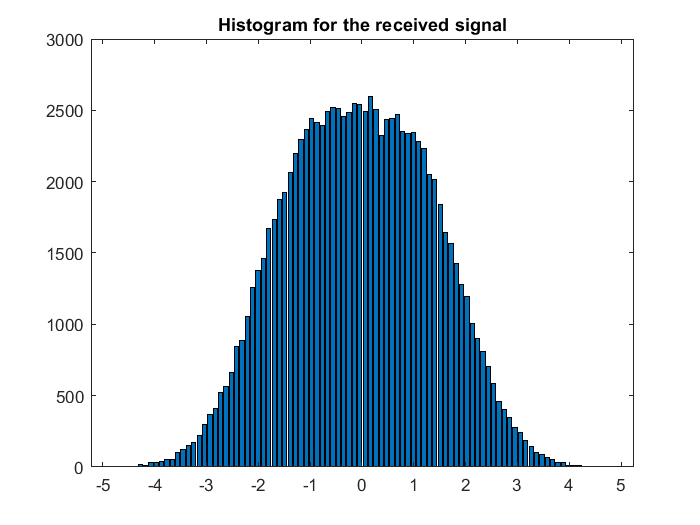


figure;
bar(bin_lims(1:bins),heights)
title('Histogram for the received signal')

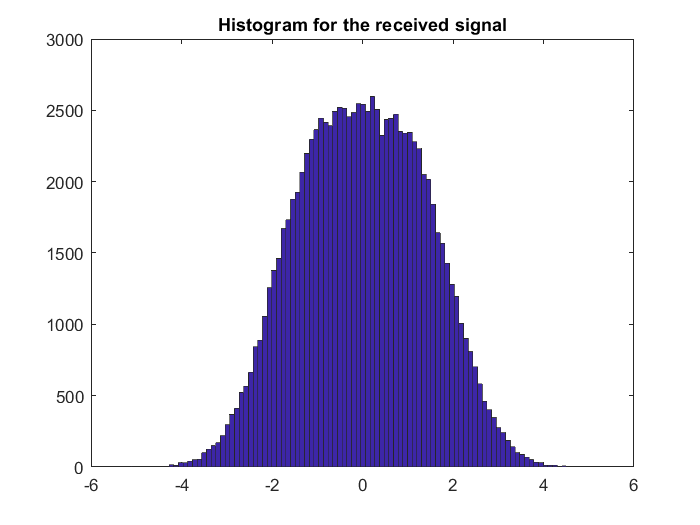


%Using the built-in function; hist
figure;
hist(R, bins);
title('Histogram for the received signal')

**Question 05 (b)**

Plotting the pdf of $f_{R|S}(r|S=A)$

R_S_pos_A = R(S==A); %Extracting R vals when S=A

%we will use 100 bins
bins = 100;
h1 = histogram(R_S_pos_A,'NumBins',bins,'Normalization','probability') %Normalizing

h1 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0835
        BinLimits: [-3.1200 5.2300]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

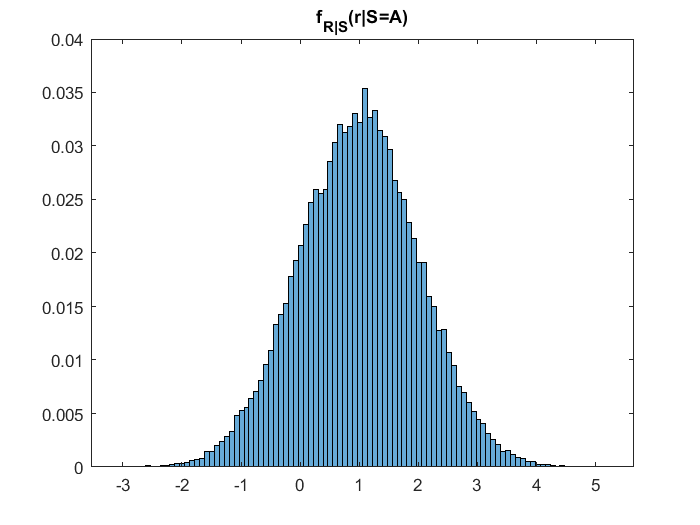

title('f_{R|S}(r|S=A)')


x1 = h1.Values;
y1 = h1.BinEdges;

Plotting the pdf of $f_{R|S}(r|S=-A)$

R_S_neg_A = R(S==-A); %Extracting R vals when S=-A

%we will use 100 bins
bins = 100;
h2 = histogram(R_S_neg_A,'NumBins',bins,'Normalization','probability') %Normalizing

h2 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0877
        BinLimits: [-5.1200 3.6500]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

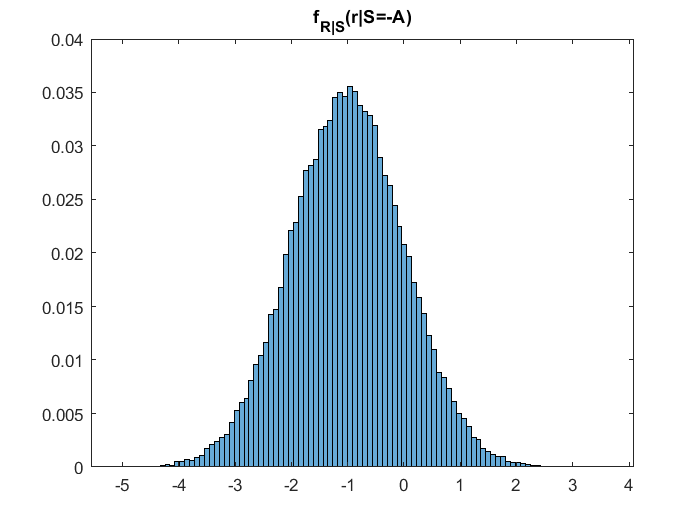

title('f_{R|S}(r|S=-A)')


x2 = h2.Values;
y2 = h2.BinEdges;

**Question 05 (c)**

Finding $E[R|S=A],\ E[R|S=-A]\ and\ E[R]$

%Finding E[R|S=A]
E_R_S_pos_A = 0;
for i = 1:bins
    E_R_S_pos_A = E_R_S_pos_A + (x1(i)*(0.5*(y1(i)+y1(i+1))));
end

%Finding E[R|S=-A]
E_R_S_neg_A = 0;
for i = 1:bins
    E_R_S_neg_A = E_R_S_neg_A + (x2(i)*(0.5*(y2(i)+y2(i+1))));
end

h3 = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h3 =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1050
        BinLimits: [-5.2000 5.3000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

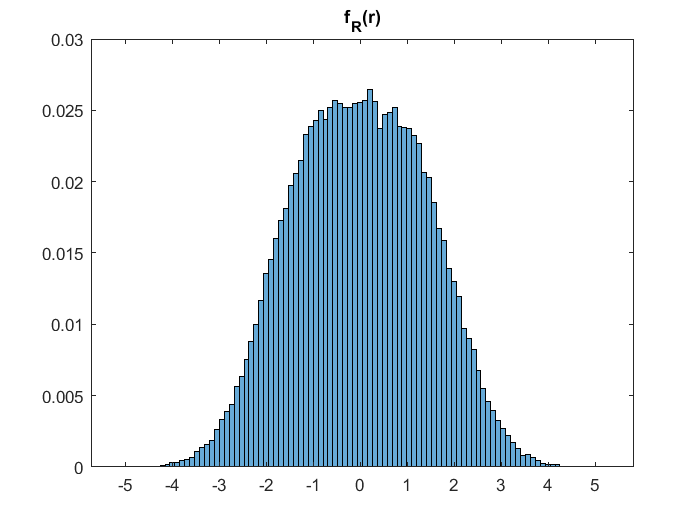

title('f_{R}(r)')


x3 = h3.Values;
y3 = h3.BinEdges;

E_R = 0;
for i = 1:bins
    E_R = E_R + (x3(i)*(0.5*(y3(i)+y3(i+1))));
end

**Question 05 (d)**

Sketching the PDF $f_{R}(r)
$

h = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1050
        BinLimits: [-5.2000 5.3000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

title('f_{R}(r)')

**Question 06**

Including interference (R = S + N + I)

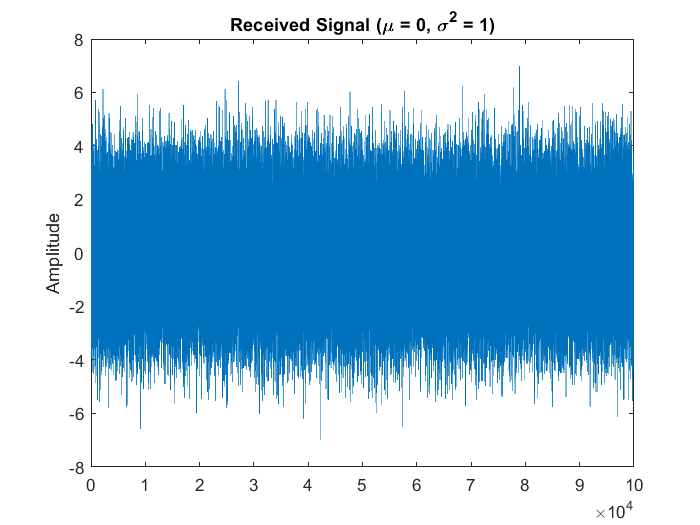

L = 100000; %Length of the sequence
D = zeros(1,L);

rng('default')
j = randperm(L,L/2); %random indices
D(j) = 1; % D--> equiprobable data array

A = 1; %Amplitude of the rectangular pulses
S = zeros(1,L); %Stream of rectangular pulses
S(D==1) = A;
S(D==0) = -A;

mu = 0; %Mean of the noise
sigma = 1; %Standard deviation
N = normrnd(mu, sigma, [1,L]); %AWGN

mu_i = 0; %Mean of the interference
sigma_i = 1;%Standard deviation of the interference
I = normrnd(mu_i, sigma_i, [1,L]);

R = S + N + I; %Received signal
figure;
plot(R)
title('Received Signal (\mu = 0, \sigma^{2} = 1)')
ylabel('Amplitude')

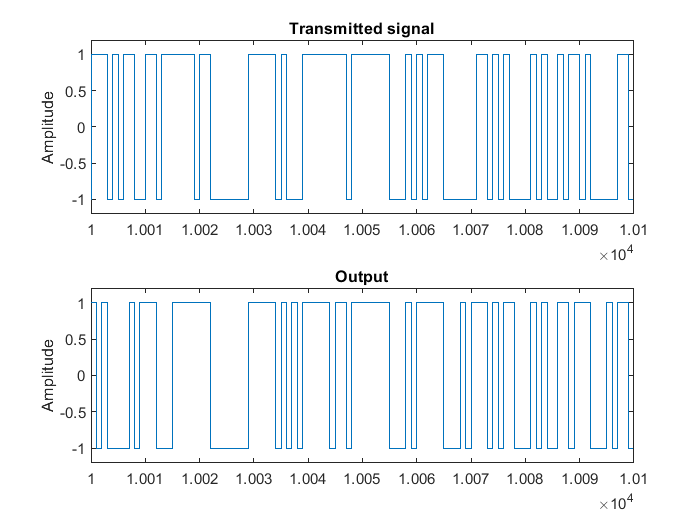


tau = 0; %threshold
Y = zeros(1,L); %Final output
Y(R>tau) = A;
Y(R<=tau) = -A;

%Comparing the transmitted signal S and the output Y
figure;
subplot(2,1,1);
stairs(S)
title('Transmitted signal')
ylim([-1.2,1.2])
xlim([10000,10100]) %limiting the x-range to view the differences
ylabel('Amplitude')

subplot(2,1,2);
stairs(Y)
title('Output')
ylim([-1.2,1.2])
xlim([10000,10100])
ylabel('Amplitude')


%Calculating the error percentage
error = (sum(Y ~= S))*100/L'

error = 24.0460

sprintf('The error percentage is %.2f%%', error)

ans = 'The error percentage is 24.05%'

Plotting the pdf of $f_{R|S}(r|S=A)$

R_S_pos_A = R(S==A); %Extracting R vals when S=A

%we will use 100 bins
bins = 100;
figure;
h1 = histogram(R_S_pos_A,'NumBins',bins,'Normalization','probability') %Normalizing

h1 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1220
        BinLimits: [-5.2000 7.0000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

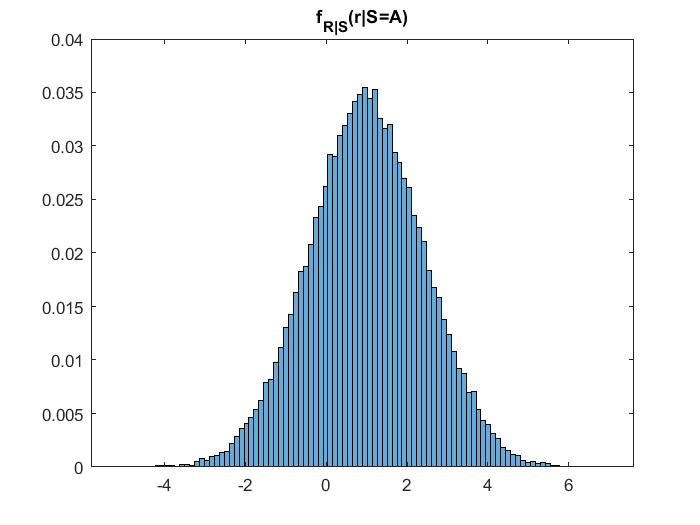

title('f_{R|S}(r|S=A)')


x1 = h1.Values;
y1 = h1.BinEdges;

Plotting the pdf of $f_{R|S}(r|S=-A)$

R_S_neg_A = R(S==-A); %Extracting R vals when S=-A

%we will use 100 bins
bins = 100;
h2 = histogram(R_S_neg_A,'NumBins',bins,'Normalization','probability') %Normalizing

h2 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1200
        BinLimits: [-7 5]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

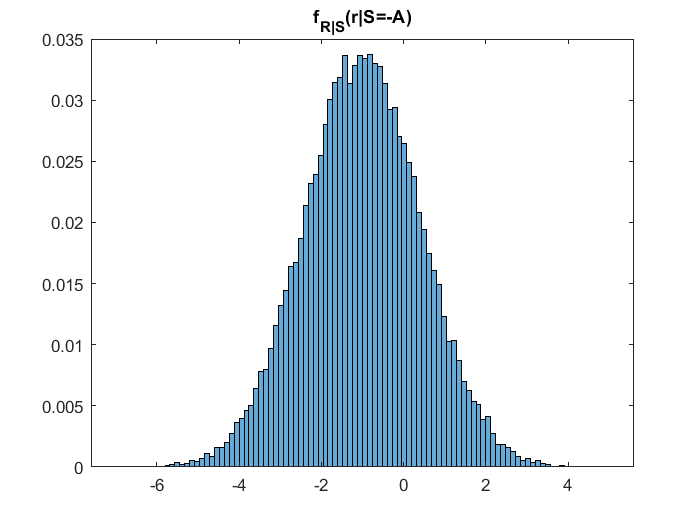

title('f_{R|S}(r|S=-A)')


x2 = h2.Values;
y2 = h2.BinEdges;

Finding $E[R|S=A],\ E[R|S=-A]\ and\ E[R]$

%Finding E[R|S=A]
E_R_S_pos_A = 0;
for i = 1:bins
    E_R_S_pos_A = E_R_S_pos_A + (x1(i)*(0.5*(y1(i)+y1(i+1))));
end

%Finding E[R|S=-A]
E_R_S_neg_A = 0;
for i = 1:bins
    E_R_S_neg_A = E_R_S_neg_A + (x2(i)*(0.5*(y2(i)+y2(i+1))));
end

h3 = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h3 =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1400
        BinLimits: [-7 7.0000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

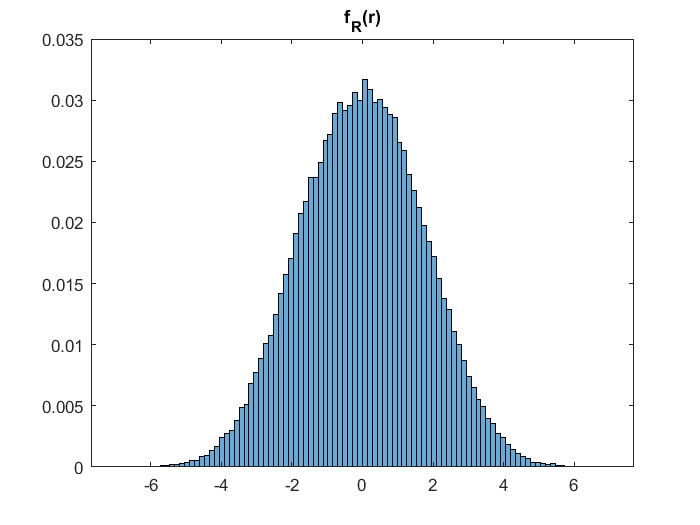

title('f_{R}(r)')


x3 = h3.Values;
y3 = h3.BinEdges;

E_R = 0;
for i = 1:bins
    E_R = E_R + (x3(i)*(0.5*(y3(i)+y3(i+1))));
end

Sketching the PDF $f_{R}(r)
$

h = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1400
        BinLimits: [-7 7.0000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

title('f_{R}(r)')

**Question 07**

Impact of Scaling  - $R = \alpha S + N$

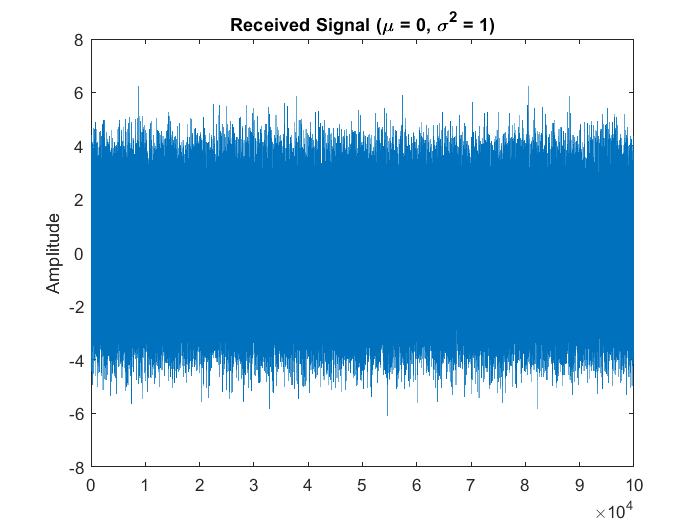

L = 100000; %Length of the sequence
D = zeros(1,L);
alpha = 2;

rng('default')
j = randperm(L,L/2); %random indices
D(j) = 1; % D--> equiprobable data array

A = 1; %Amplitude of the rectangular pulses
S = zeros(1,L); %Stream of rectangular pulses
S(D==1) = A;
S(D==0) = -A;

mu = 0; %Mean
sigma = 1; %Standard deviation
N = normrnd(mu, sigma, [1,L]); %AWGN

R = alpha*S + N; %Received signal
figure;
plot(R)
title('Received Signal (\mu = 0, \sigma^{2} = 1)')
ylabel('Amplitude')

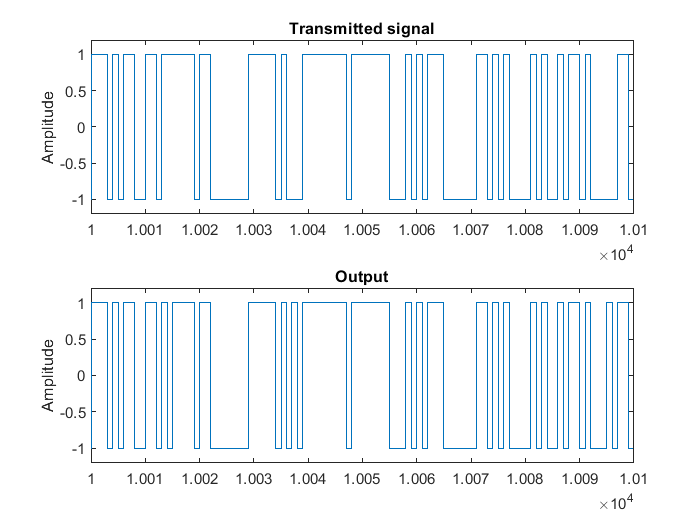


tau = 0; %threshold
Y = zeros(1,L); %Final output
Y(R>tau) = A;
Y(R<=tau) = -A;

%Comparing the transmitted signal S and the output Y
figure;
subplot(2,1,1);
stairs(S)
title('Transmitted signal')
ylim([-1.2,1.2])
xlim([10000,10100]) %limiting the x-range to view the differences
ylabel('Amplitude')

subplot(2,1,2);
stairs(Y)
title('Output')
ylim([-1.2,1.2])
xlim([10000,10100])
ylabel('Amplitude')


%Calculating the error percentage
error = (sum(Y ~= S))*100/L'

error = 2.3920

sprintf('The error percentage is %.2f%%', error)

ans = 'The error percentage is 2.39%'

Plotting the pdf of $f_{R|S}(r|S=A)$

R_S_pos_A = R(S==A); %Extracting R vals when S=A

%we will use 100 bins
bins = 100;
figure;
h1 = histogram(R_S_pos_A,'NumBins',bins,'Normalization','probability') %Normalizing

h1 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0831
        BinLimits: [-2.0800 6.2300]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

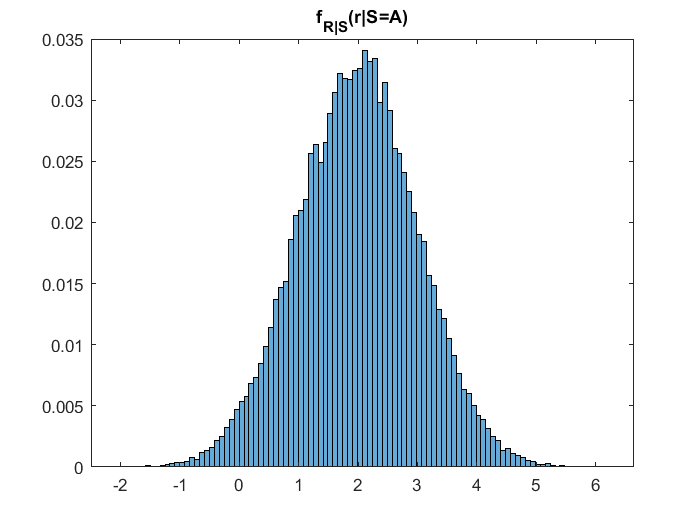

title('f_{R|S}(r|S=A)')


x1 = h1.Values;
y1 = h1.BinEdges;

Plotting the pdf of $f_{R|S}(r|S=-A)$

R_S_neg_A = R(S==-A); %Extracting R vals when S=-A

%we will use 100 bins
bins = 100;
h2 = histogram(R_S_neg_A,'NumBins',bins,'Normalization','probability') %Normalizing

h2 =   Histogram with properties:

             Data: [1×50000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.0881
        BinLimits: [-6.1600 2.6500]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

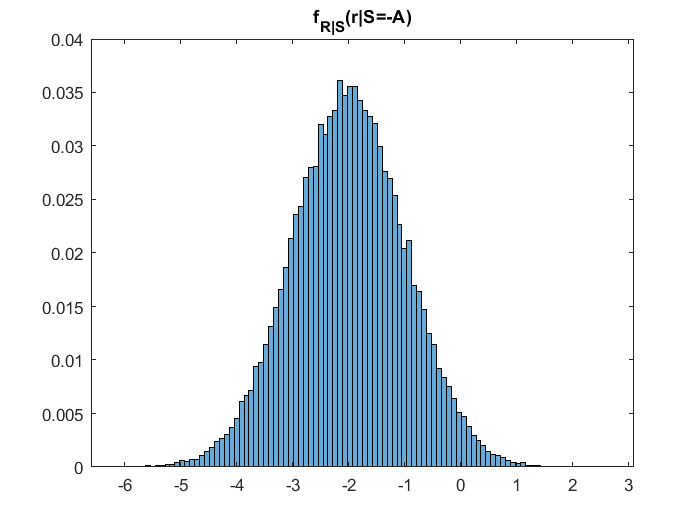

title('f_{R|S}(r|S=-A)')


x2 = h2.Values;
y2 = h2.BinEdges;

Finding $E[R|S=A],\ E[R|S=-A]\ and\ E[R]$

%Finding E[R|S=A]
E_R_S_pos_A = 0;
for i = 1:bins
    E_R_S_pos_A = E_R_S_pos_A + (x1(i)*(0.5*(y1(i)+y1(i+1))));
end

%Finding E[R|S=-A]
E_R_S_neg_A = 0;
for i = 1:bins
    E_R_S_neg_A = E_R_S_neg_A + (x2(i)*(0.5*(y2(i)+y2(i+1))));
end

h3 = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h3 =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1250
        BinLimits: [-6.2000 6.3000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

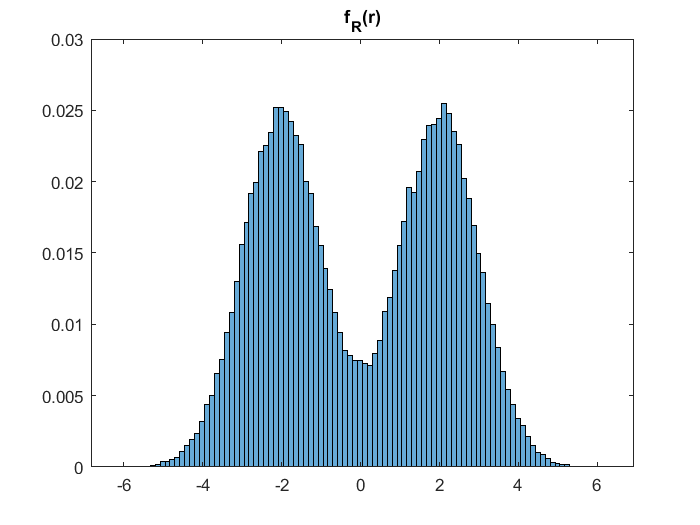

title('f_{R}(r)')


x3 = h3.Values;
y3 = h3.BinEdges;

E_R = 0;
for i = 1:bins
    E_R = E_R + (x3(i)*(0.5*(y3(i)+y3(i+1))));
end

Sketching the PDF $f_{R}(r)
$

h = histogram(R,'NumBins',bins,'Normalization','probability') %Normalizing

h =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×100 double]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 0.1250
        BinLimits: [-6.2000 6.3000]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

title('f_{R}(r)')